## Robustness against non-sharp energy degeneracies

We do the following. Suppose the energy levels are not exactly the optimal ones. Instead, they are two Gaussian distributions, with a width sigma, and a mu0=0, and mu1=epsilon, where epsilon is the optimal gap. 

What happens to the QFI? Is it still behaving well?

Due two things. 1: For a small width, see how things work with increasing n

2: For a fixed n, see how things work with sigma.

Here, we only look at the fermionic case.

### First, fix n=10, and run for different sigma

% n=10;
% sigma_vec=0.01:0.1:2;
% s=length(sigma_vec);
% ro_fisher=zeros(1,s);
% op_fisher=zeros(1,s);
% for is=1:s
% sigma=sigma_vec(1,is);
% robustness_ham_structure;
% ro_fisher(1,is)=r_fisher;
% op_fisher(1,is)=opt_fisher;
% end

% figure
% semilogx(sigma_vec,[op_fisher;ro_fisher])

### Secondly, fix sigma=.1, and run for different n

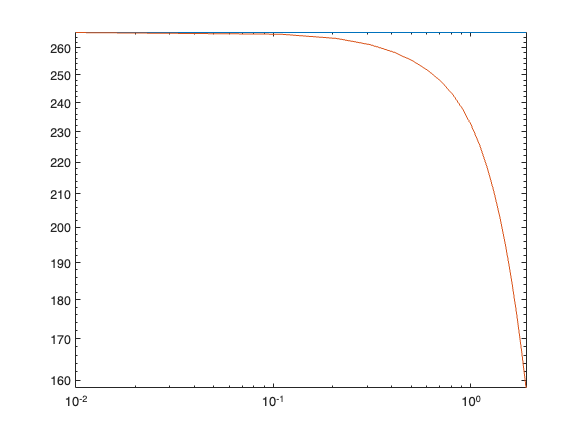

% n_vec=[4:1:12];
% sigma=1;
% s=length(n_vec);
% ro_fisher=zeros(1,s);
% op_fisher=zeros(1,s);
% for is=1:s
% n=n_vec(1,is);
% robustness_ham_structure;
% ro_fisher(1,is)=r_fisher;

% op_fisher(1,is)=opt_fisher;
% end

% figure
% semilogy(n_vec,[op_fisher;ro_fisher])
% histogram(eps_vec,2^(n-4),'EdgeColor', 'none')

## Mix everything nicely for a single graph

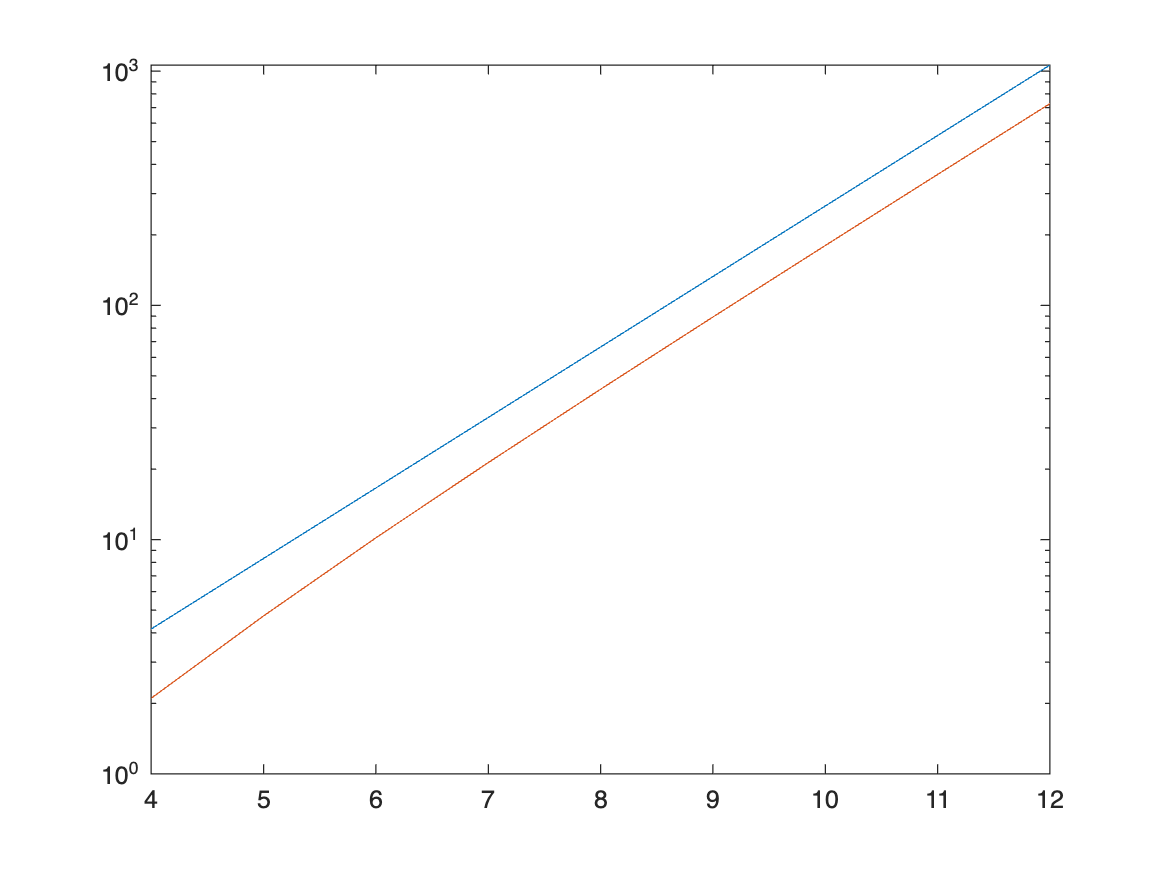

n_vec=[4:1:12];
sigma_vec=[0.1,.5,1];
sn=length(n_vec);
ss=length(sigma_vec);
ro_fisher=zeros(ss,sn);
op_fisher=zeros(ss,sn);
figure
for iss=1:ss
sigma=sigma_vec(1,iss);
for isn=1:sn
n=n_vec(1,isn);

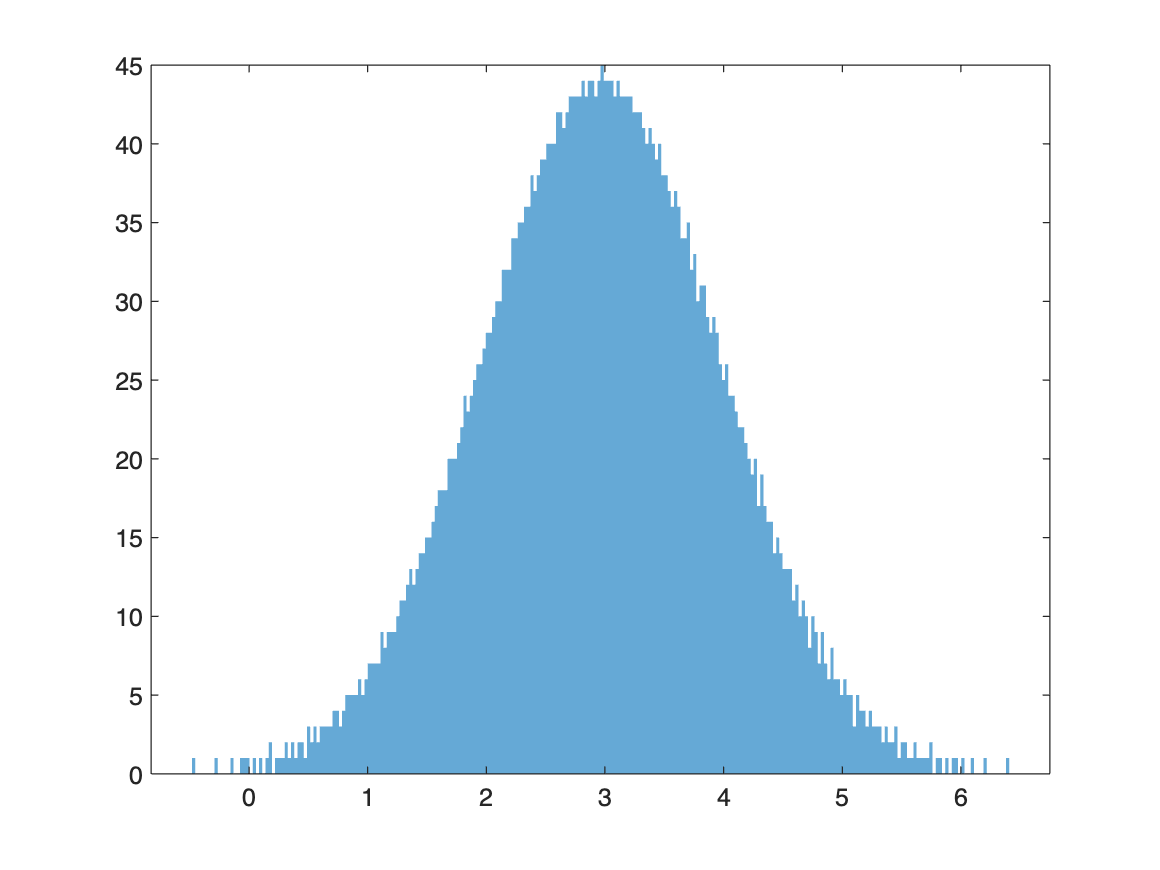

robustness_ham_structure;

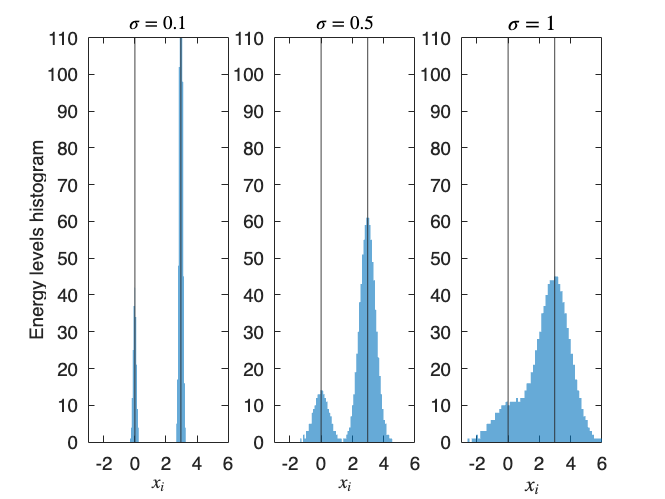

ro_fisher(iss,isn)=r_fisher;
op_fisher(iss,isn)=opt_fisher;
if n==10
subplot(1,3,iss)
xline([0,x_opt],'LineStyle','-','LineWidth',1)
hold on
histogram(eps_vec,2^(n-4),'EdgeColor', 'none')
fontsize(15,"points")
xlim([-3,6])
ylim([0,110])
xlabel('$x_i$','Interpreter','latex')
title(['$\sigma=$',num2str(sigma)],'Interpreter','latex')
if iss==1
ylabel('Energy levels histogram')
end
box on
end
end
end

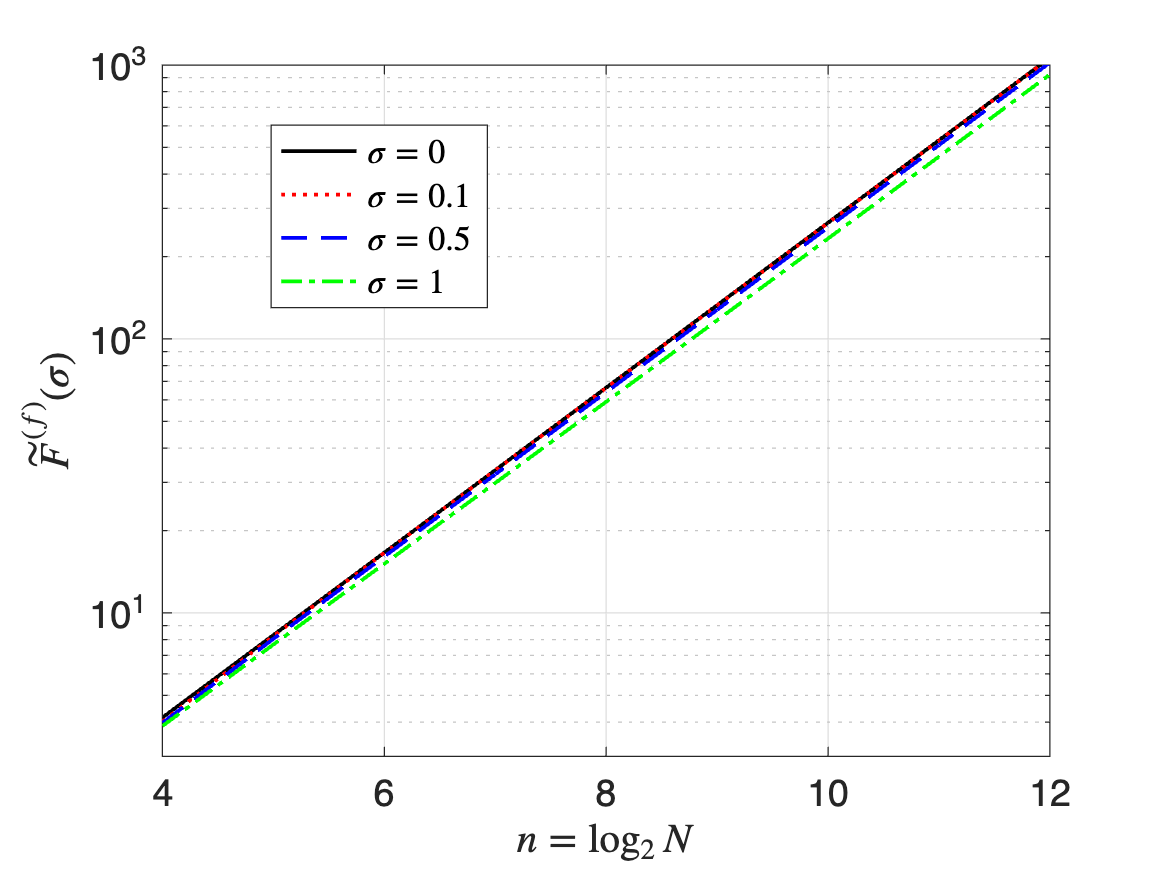

figure
semilogy(n_vec,op_fisher(1,:),'k-', ...
    n_vec,ro_fisher(1,:),'r:',...
    n_vec,ro_fisher(2,:),'b--',...
    n_vec,ro_fisher(3,:),'g-.','LineWidth',1.5)
fontsize(15,"points")
xlim([4,12])
ylim([3,1000])
xlabel('$n=\log_2 N$','Interpreter','latex')
ylabel('${\tilde F}^{(f)}(\sigma)$','Interpreter','latex')
box on
grid on
legend('$\sigma = 0$','$\sigma = 0.1$','$\sigma = 0.5$','$\sigma = 1$'...
    ,'Interpreter','latex')